# Exercicis Full 1

n = 10;
sum(1:n)

ans =     55


n = 10; p = 5;
sum((1:n).^p)

ans =       220825


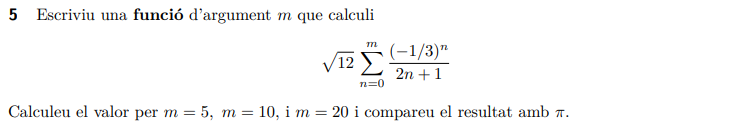

m = 5;
ret = serie1(m);
[ea, er, ep] = funerror(ret, pi);
s1 = [m,ret,ea,er,ep];

m = 10;
ret = serie1(m);
[ea, er, ep] = funerror(ret, pi);
s2 = [m,ret,ea,er,ep];

m = 20;
ret = serie1(m);
[ea, er, ep] = funerror(ret, pi);
s3 = [m,ret,ea,er,ep];

format long
array2table([s1;s2;s3], 'VariableNames', {'m', 'serie', 'ea', 'er', 'ep'} )

ans = 3×5 table
    m          serie                   ea                      er                      ep         
    __    ________________    ____________________    ____________________    ____________________

     5    3.14130878546288    0.000283868126909947    9.03580311679112e-05     0.00903580311679112
    10    3.14159330450308     6.5091328815825e-07     2.0719213466917e-07     2.0719213466917e-05
    20    3.14159265359564    5.84199355557757e-12    1.85956430376234e-12    1.85956430376234e-10


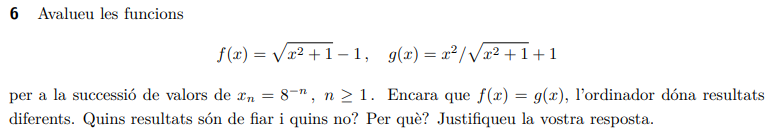

f = @(x) sqrt(x.^2 + 1) - 1;
g = @(x) x.^2 ./ (sqrt(x.^2 + 1) + 1);

k = 0:n;
xn = 8.^(-k);

format short g
array2table([k; xn; f(xn); g(xn)]', 'VariableNames', {'n', 'x', 'fx', 'gx'} )

ans = 11×4 table
    n         x             fx            gx    
    __    __________    __________    __________

     0             1       0.41421       0.41421
     1         0.125     0.0077822     0.0077822
     2      0.015625    0.00012206    0.00012206
     3     0.0019531    1.9073e-06    1.9073e-06
     4    0.00024414    2.9802e-08    2.9802e-08
     5    3.0518e-05    4.6566e-10    4.6566e-10
     6    3.8147e-06     7.276e-12     7.276e-12
     7    4.7684e-07    1.1369e-13    1.1369e-13
     8    5.9605e-08    1.7764e-15    1.7764e-15
     9    7.4506e-09             0    2.7756e-17
    10    9.3132e-10             0    4.3368e-19


Es mejor la funcion que no cancela terminos, ya que en algun momento ha restado dos elementos muy cercanos y los bits de la mantisa han pasado a ser 0 y han perdido la informacion.